%% b
ao = 50.8/2;
a = (0:1:600);
R = 6.95e3*(a - ao).^0.5;
dRda = (6.95e3*(a-ao).^-0.5)/2;
sigma = 138e6;
E = 207e9;
G = (pi*a*10^-3*sigma^2)./E;
plot(a, R)

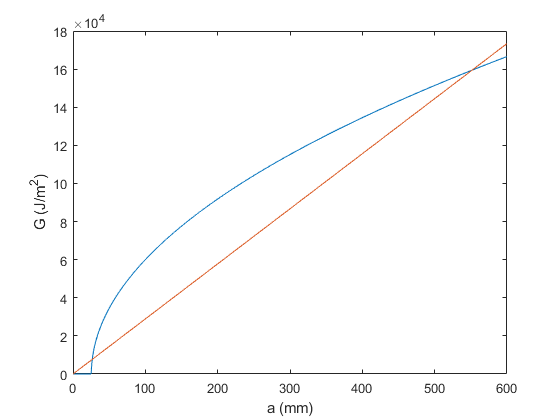

hold on
plot(a, G)
xlabel('a (mm)')
ylabel('G (J/m^2)')

figure
plot(a, dRda)

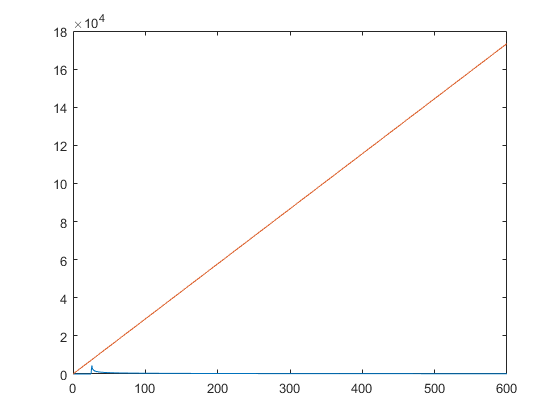

hold on
plot(a, G)


% find the intersection of the two lines
[~, index] = min(abs(R./G - 1));
fprintf('i. stress at failure: %3.0f MPa \n', G(index)/(a(index)))

i. stress at failure: 289 MPa 


fprintf('ii. half crack length at failure: %d mm \n', a(index))

ii. half crack length at failure: 552 mm 


This criteria gave the second intersection point of the two lines, which occurs when G=R and 

## 4b.

Kic = [218 65 131 196];     % fracture toughness for each material
t = [1:100]*10^-3;          % range of wall thicknesses deemed acceptable (by me)

K = Kic.*t';
materialtf = sum(K > 18.96)

materialtf =     14     0     0     4


Materials 2 and 3 will not work for any acceptable thickness.

% determine minimum thickness for materials 1 and 4
tmin_mat1 = t(end-14)

tmin_mat1 = 0.0860

tmin_mat4 = t(end-4)

tmin_mat4 = 0.0960

Material 1 fits the 'leak before break' criterion if the thickness is > 86mm

Material 2 fits the 'leak before break' criterion if the thickness is > 96mm

% identify if these materials fulfill the 0.8*sigma_yt criterion at these thicknesses
sigma_yt = [206 1723 896 586];      % yield stress for each material
tmin_mat1*sigma_yt(1) > 11.85

ans = logical
   1


tmin_mat4*sigma_yt(4) > 11.85

ans = logical
   1


In both cases, the vessel will not yield before it leaks.  

## 4c.

For 1020 steel, I would recommend a minimum thickness of 86mm.  

For A533B, I would recommend a miniumu thickness of 96mm.

Estimates up to this point have been conservative so appropriate factors of safety should already be incorporated, therefore I did not incorporate any further safety factors into my recommendations